# 4-clusters problem with a multilayer perceptron

## 1.Define 4 clusters of input data

close all, clear all, clc, format compact

#### 1.1 number of samples of each class

K = 100;

#### 1.2 offset of classes

q = .6; 

#### 1.3 define 4 clusters of input data

A = [rand(1,K)-q; rand(1,K)+q];
B = [rand(1,K)+q; rand(1,K)+q];
C = [rand(1,K)+q; rand(1,K)-q];
D = [rand(1,K)-q; rand(1,K)-q];

#### 1.4 plot clusters

figure(1)
plot(A(1,:),A(2,:),'k+')
hold on
grid on
plot(B(1,:),B(2,:),'b*')
plot(C(1,:),C(2,:),'kx')
plot(D(1,:),D(2,:),'bd')

#### 1.5 text labels for clusters

text(.5-q,.5+2*q,'Class A')
text(.5+q,.5+2*q,'Class B')
text(.5+q,.5-2*q,'Class C')
text(.5-q,.5-2*q,'Class D')

## 2.Define output coding for all 4 clusters

#### 2.1 coding (+1/-1) of 4 separate classes

a = [-1 -1 -1 +1]';
b = [-1 -1 +1 -1]';
d = [-1 +1 -1 -1]';
c = [+1 -1 -1 -1]';

## 3.Prepare inputs & outputs for network training

#### 3.1 define inputs (combine samples from all four classes)

P = [A B C D];

#### 3.2 define targets

T = [repmat(a,1,length(A)) repmat(b,1,length(B)) ...
repmat(c,1,length(C)) repmat(d,1,length(D)) ];

## 4.Create and train a multilayer perceptron

#### create a neural network

net = feedforwardnet([4 3]);

####  train net

net.divideParam.trainRatio = 1; % training set [%]
net.divideParam.valRatio = 0; % validation set [%]
net.divideParam.testRatio = 0; % test set [%]

#### train a neural network

[net,tr,Y,E] = train(net,P,T);

#### show network

view(net)

## 5.Evaluate network performance and plot results

### evaluate performance: decoding network response

#### 5.1 target class

[m,i] = max(T); 

#### 5.2 predicted class

[m,j] = max(Y); 

#### 5.3 number of all samples

N = length(Y); 

#### 5.4 number of missclassified samples

k = 0; 

#### 5.5 if there exist missclassified samples

if find(i-j), 
k = length(find(i-j)); % get a number of missclassified samples
end
fprintf('Correct classified samples: %.1f%% samples\n', 100*(N-k)/N)

Correct classified samples: 100.0% samples


#### 5.6 plot network output

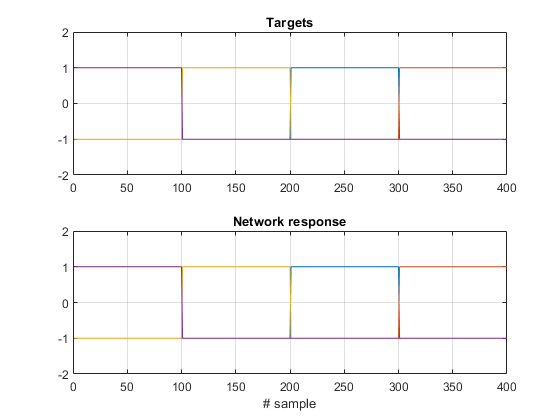

figure;
subplot(211)
plot(T')
title('Targets')
ylim([-2 2])
grid on
subplot(212)
plot(Y')
title('Network response')
xlabel('# sample')
ylim([-2 2])
grid on

## 6. Plot classification result for the complete input space

#### 6.1 generate a grid

span = -1:.01:2;
[P1,P2] = meshgrid(span,span);
pp = [P1(:) P2(:)]';

#### 6.2 simualte neural network on a grid

aa = net(pp);

#### 6.3 plot classification regions based on MAX activation

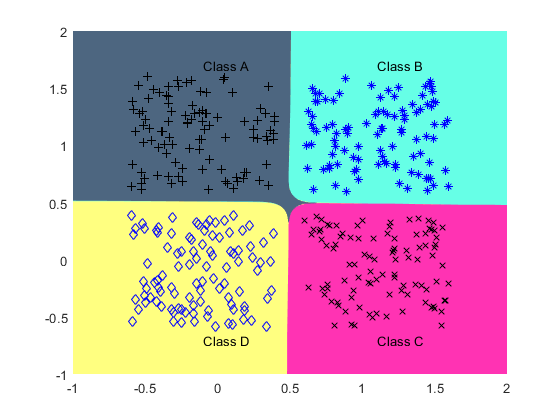

figure(1)
m = mesh(P1,P2,reshape(aa(1,:),length(span),length(span))-5);
set(m,'facecolor',[1 0.2 .7],'linestyle','none');
hold on
m = mesh(P1,P2,reshape(aa(2,:),length(span),length(span))-5);
set(m,'facecolor',[1 1.0 0.5],'linestyle','none');
m = mesh(P1,P2,reshape(aa(3,:),length(span),length(span))-5);
set(m,'facecolor',[.4 1.0 0.9],'linestyle','none');
m = mesh(P1,P2,reshape(aa(4,:),length(span),length(span))-5);
set(m,'facecolor',[.3 .4 0.5],'linestyle','none');
view(2)